# **IBME**

# **Computer Assignment 1**

## Hossein Atrsaei

## 
$$\left.\textrm{Part}\;1\right)$$


rng(1)
v1 = load('v1.mat');
v2 = load('v2.mat');
v3 = load('v3.mat');
idx = randi(64,1,3);
x1 = v1.val(idx(1),:);
x2 = v2.val(idx(2),:);
x3 = v3.val(idx(3),:);
fs = length(x1)/10;  %f=0
t = 0:1/fs:10-1/fs;
freq = (0:(length(x1)-1))/length(x1) *fs - fs/2;
f0 = length(freq)/2+1;
f1 = length(freq)/fs;
X1 = FT(x1);
X2 = FT(x2);
X3 = FT(x3);
%Cancel Noise in f=0
X1 = filter_noise(X1,fs);
X2 = filter_noise(X2,fs);
X3 = filter_noise(X3,fs);

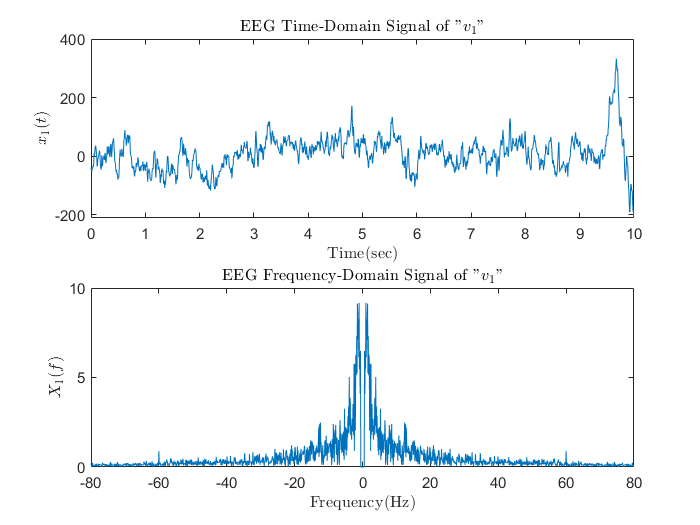

figure
subplot(2,1,1)
plot(t,x1)
title('EEG Time-Domain Signal of "$v_1$"',"Interpreter","latex")
xlabel('Time(sec)',"Interpreter","latex")
ylabel('$x_1(t)$',"Interpreter","latex")
subplot(2,1,2)
plot(freq,abs(X1))
title('EEG Frequency-Domain Signal of "$v_1$"',"Interpreter","latex")
xlabel('Frequency(Hz)',"Interpreter","latex")
ylabel('$X_1(f)$',"Interpreter","latex")

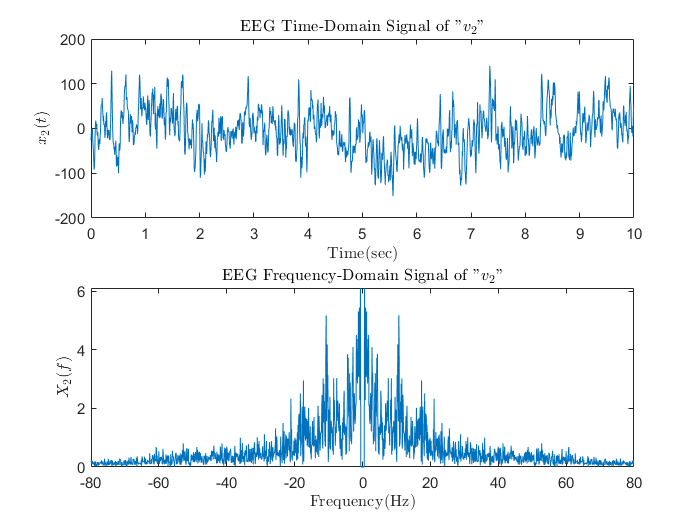

figure
subplot(2,1,1)
plot(t,x2)
title('EEG Time-Domain Signal of "$v_2$"',"Interpreter","latex")
xlabel('Time(sec)',"Interpreter","latex")
ylabel('$x_2(t)$',"Interpreter","latex")
subplot(2,1,2)
plot(freq,abs(X2))
title('EEG Frequency-Domain Signal of "$v_2$"',"Interpreter","latex")
xlabel('Frequency(Hz)',"Interpreter","latex")
ylabel('$X_2(f)$',"Interpreter","latex")

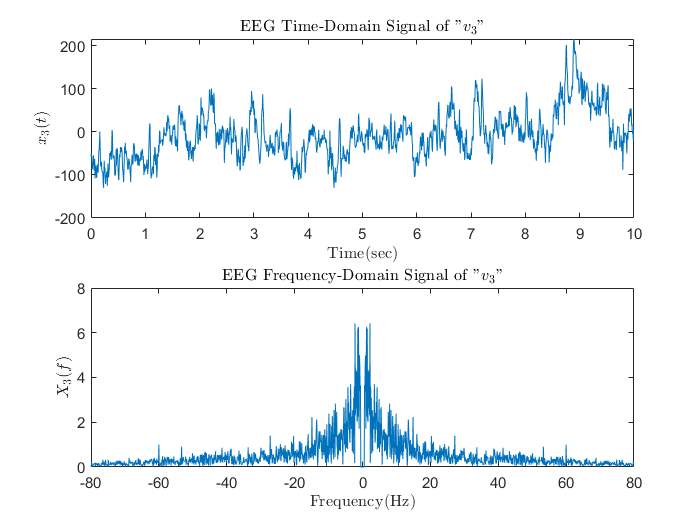

figure
subplot(2,1,1)
plot(t,x3)
title('EEG Time-Domain Signal of "$v_3$"',"Interpreter","latex")
xlabel('Time(sec)',"Interpreter","latex")
ylabel('$x_3(t)$',"Interpreter","latex")
subplot(2,1,2)
plot(freq,abs(X3))
title('EEG Frequency-Domain Signal of "$v_3$"',"Interpreter","latex")
xlabel('Frequency(Hz)',"Interpreter","latex")
ylabel('$X_3(f)$',"Interpreter","latex")

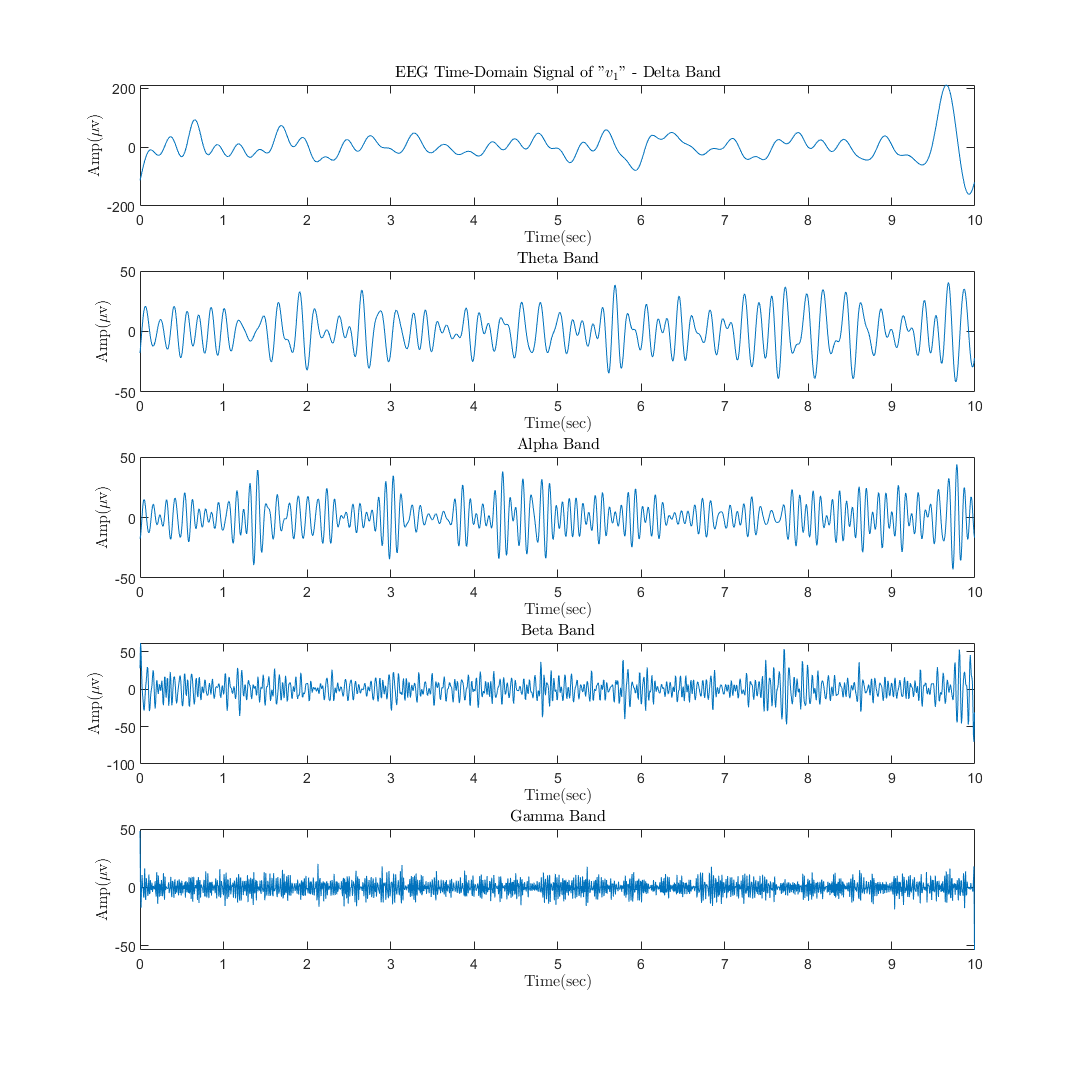

x1_delta = delta(X1,fs);
x1_theta = theta(X1,fs);
x1_alpha = alpha(X1,fs);
x1_beta = beta(X1,fs);
x1_gamma = gamma(X1,fs);
figure('Position',[0 0 1000 1000])
subplot(5,1,1)
plot(t,x1_delta)
title('EEG Time-Domain Signal of "$v_1$" - Delta Band',"Interpreter","latex")
xlabel('Time(sec)',"Interpreter","latex")
ylabel('Amp($\mu$v)',"Interpreter","latex")
subplot(5,1,2)
plot(t,x1_theta)
title('Theta Band',"Interpreter","latex")
xlabel('Time(sec)',"Interpreter","latex")
ylabel('Amp($\mu$v)',"Interpreter","latex")
subplot(5,1,3)
plot(t,x1_alpha)
title('Alpha Band',"Interpreter","latex")
xlabel('Time(sec)',"Interpreter","latex")
ylabel('Amp($\mu$v)',"Interpreter","latex")
subplot(5,1,4)
plot(t,x1_beta)
title('Beta Band',"Interpreter","latex")
xlabel('Time(sec)',"Interpreter","latex")
ylabel('Amp($\mu$v)',"Interpreter","latex")
subplot(5,1,5)
plot(t,x1_gamma)
title('Gamma Band',"Interpreter","latex")
xlabel('Time(sec)',"Interpreter","latex")
ylabel('Amp($\mu$v)',"Interpreter","latex")

## 
$$\left.\textrm{Part}\;2\right)$$


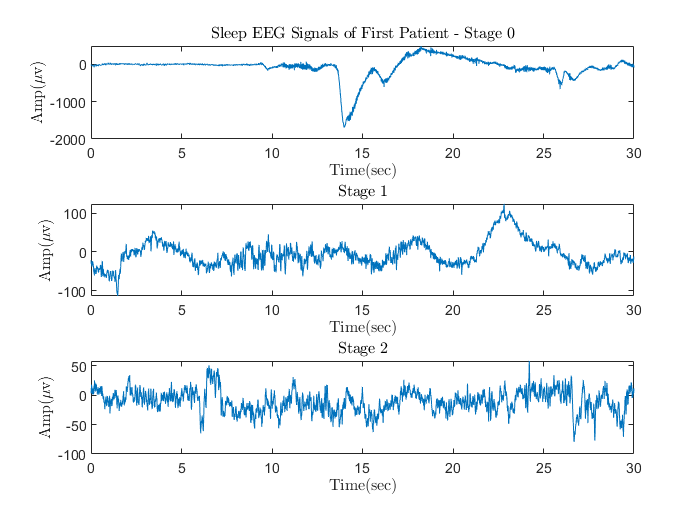

v = load('matlab.mat');
fs = v.stage0.Fs(1,1);
p1_s0 = v.stage0.Data(:,1);
p1_s1 = v.stage1.Data(:,1);
p1_s2 = v.stage2.Data(:,1);
t = 0:1/fs:length(p1_s0)/fs-1/fs;
figure
subplot(3,1,1)
plot(t,p1_s0)
title('Sleep EEG Signals of First Patient - Stage 0',"Interpreter","latex")
xlabel('Time(sec)',"Interpreter","latex")
ylabel('Amp($\mu$v)',"Interpreter","latex")
subplot(3,1,2)
plot(t,p1_s1)
title('Stage 1',"Interpreter","latex")
xlabel('Time(sec)',"Interpreter","latex")
ylabel('Amp($\mu$v)',"Interpreter","latex")
subplot(3,1,3)
plot(t(1:length(p1_s2)),p1_s2)
title('Stage 2',"Interpreter","latex")
xlabel('Time(sec)',"Interpreter","latex")
ylabel('Amp($\mu$v)',"Interpreter","latex")

P1_s0 = transpose(FT(p1_s0));
P1_s0 = filter_noise((P1_s0),fs);

p1_s0_delta = delta(P1_s0,fs);

p1_s0_theta = theta(P1_s0,fs);

p1_s0_alpha = alpha(P1_s0,fs);

p1_s0_beta = beta(P1_s0,fs);

p1_s0_gamma = gamma(P1_s0,fs);

figure('Position',[0 0 1000 1000])
subplot(6,1,1)
plot(t,p1_s0)
title('Filtered EEG Data - Stage 0"',"Interpreter","latex")
xlabel('Time(sec)',"Interpreter","latex")
ylabel('Amp($\mu$v)',"Interpreter","latex")
subplot(6,1,2)
plot(t,p1_s0_delta)
title('Delta Band (0.5-4 Hz)',"Interpreter","latex")
xlabel('Time(sec)',"Interpreter","latex")
ylabel('Amp($\mu$v)',"Interpreter","latex")
subplot(6,1,3)
plot(t,p1_s0_theta)

title('Theta Band (4-8 Hz)',"Interpreter","latex")
xlabel('Time(sec)',"Interpreter","latex")
ylabel('Amp($\mu$v)',"Interpreter","latex")
subplot(6,1,4)
plot(t,p1_s0_alpha)

title('Alpha Band (8-13 Hz)',"Interpreter","latex")
xlabel('Time(sec)',"Interpreter","latex")
ylabel('Amp($\mu$v)',"Interpreter","latex")
subplot(6,1,5)
plot(t,p1_s0_beta)

title('Beta Band (13-35 Hz)',"Interpreter","latex")
xlabel('Time(sec)',"Interpreter","latex")
ylabel('Amp($\mu$v)',"Interpreter","latex")
subplot(6,1,6)
plot(t,p1_s0_gamma)

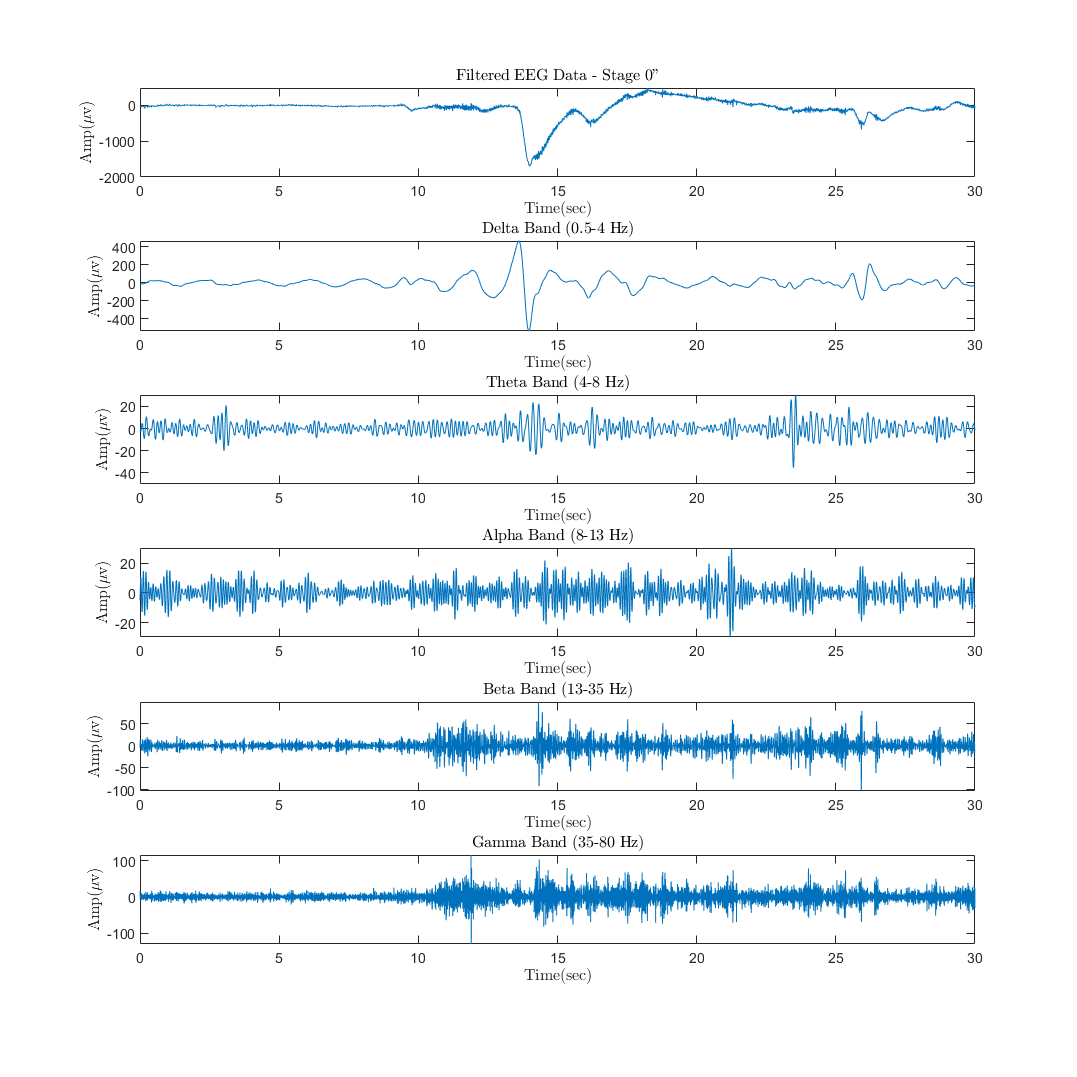

title('Gamma Band (35-80 Hz)',"Interpreter","latex")
xlabel('Time(sec)',"Interpreter","latex")
ylabel('Amp($\mu$v)',"Interpreter","latex")

P1_s1 = transpose(FT(p1_s1));
P1_s1 = filter_noise((P1_s1),fs);

p1_s1_delta = delta(P1_s1,fs);

p1_s1_theta = theta(P1_s1,fs);

p1_s1_alpha = alpha(P1_s1,fs);

p1_s1_beta = beta(P1_s1,fs);

p1_s1_gamma = gamma(P1_s1,fs);

figure('Position',[0 0 1000 1000])
subplot(6,1,1)
plot(t,p1_s1)
title('Filtered EEG Data - Stage 1"',"Interpreter","latex")
xlabel('Time(sec)',"Interpreter","latex")
ylabel('Amp($\mu$v)',"Interpreter","latex")
subplot(6,1,2)
plot(t,p1_s1_delta)
title('Delta Band (0.5-4 Hz)',"Interpreter","latex")
xlabel('Time(sec)',"Interpreter","latex")
ylabel('Amp($\mu$v)',"Interpreter","latex")
subplot(6,1,3)
plot(t,p1_s1_theta)

title('Theta Band (4-8 Hz)',"Interpreter","latex")
xlabel('Time(sec)',"Interpreter","latex")
ylabel('Amp($\mu$v)',"Interpreter","latex")
subplot(6,1,4)
plot(t,p1_s1_alpha)

title('Alpha Band (8-13 Hz)',"Interpreter","latex")
xlabel('Time(sec)',"Interpreter","latex")
ylabel('Amp($\mu$v)',"Interpreter","latex")
subplot(6,1,5)
plot(t,p1_s1_beta)

title('Beta Band (13-35 Hz)',"Interpreter","latex")
xlabel('Time(sec)',"Interpreter","latex")
ylabel('Amp($\mu$v)',"Interpreter","latex")
subplot(6,1,6)
plot(t,p1_s1_gamma)

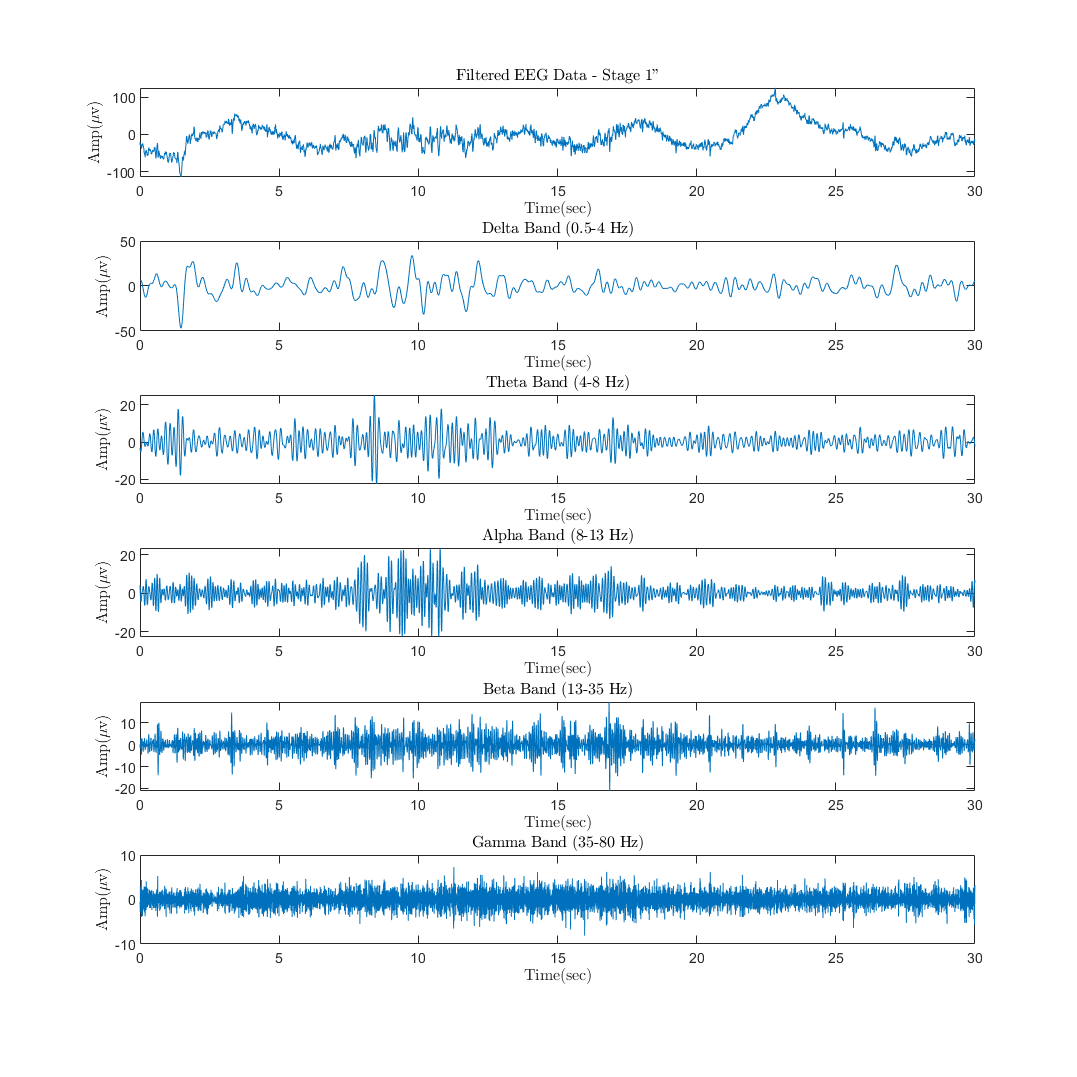

title('Gamma Band (35-80 Hz)',"Interpreter","latex")
xlabel('Time(sec)',"Interpreter","latex")
ylabel('Amp($\mu$v)',"Interpreter","latex")

P1_s2 = transpose(FT(p1_s2));
P1_s2 = filter_noise(P1_s2,fs);

p1_s2_delta = delta(P1_s2,fs);

p1_s2_theta = theta(P1_s2,fs);

p1_s2_alpha = alpha(P1_s2,fs);

p1_s2_beta = beta(P1_s2,fs);

p1_s2_gamma = gamma(P1_s2,fs);

figure('Position',[0 0 1000 1000])
subplot(6,1,1)

plot(t(1:length(p1_s2)),p1_s2)
title('Filtered EEG Data - Stage 2"',"Interpreter","latex")
xlabel('Time(sec)',"Interpreter","latex")
ylabel('Amp($\mu$v)',"Interpreter","latex")
subplot(6,1,2)
plot(t(1:length(p1_s2)),p1_s2_delta)

title('Delta Band (0.5-4 Hz)',"Interpreter","latex")
xlabel('Time(sec)',"Interpreter","latex")
ylabel('Amp($\mu$v)',"Interpreter","latex")
subplot(6,1,3)
plot(t(1:length(p1_s2)),p1_s2_theta)

title('Theta Band (4-8 Hz)',"Interpreter","latex")
xlabel('Time(sec)',"Interpreter","latex")
ylabel('Amp($\mu$v)',"Interpreter","latex")
subplot(6,1,4)
plot(t(1:length(p1_s2)),p1_s2_alpha)

title('Alpha Band (8-13 Hz)',"Interpreter","latex")
xlabel('Time(sec)',"Interpreter","latex")
ylabel('Amp($\mu$v)',"Interpreter","latex")
subplot(6,1,5)
plot(t(1:length(p1_s2)),p1_s2_beta)

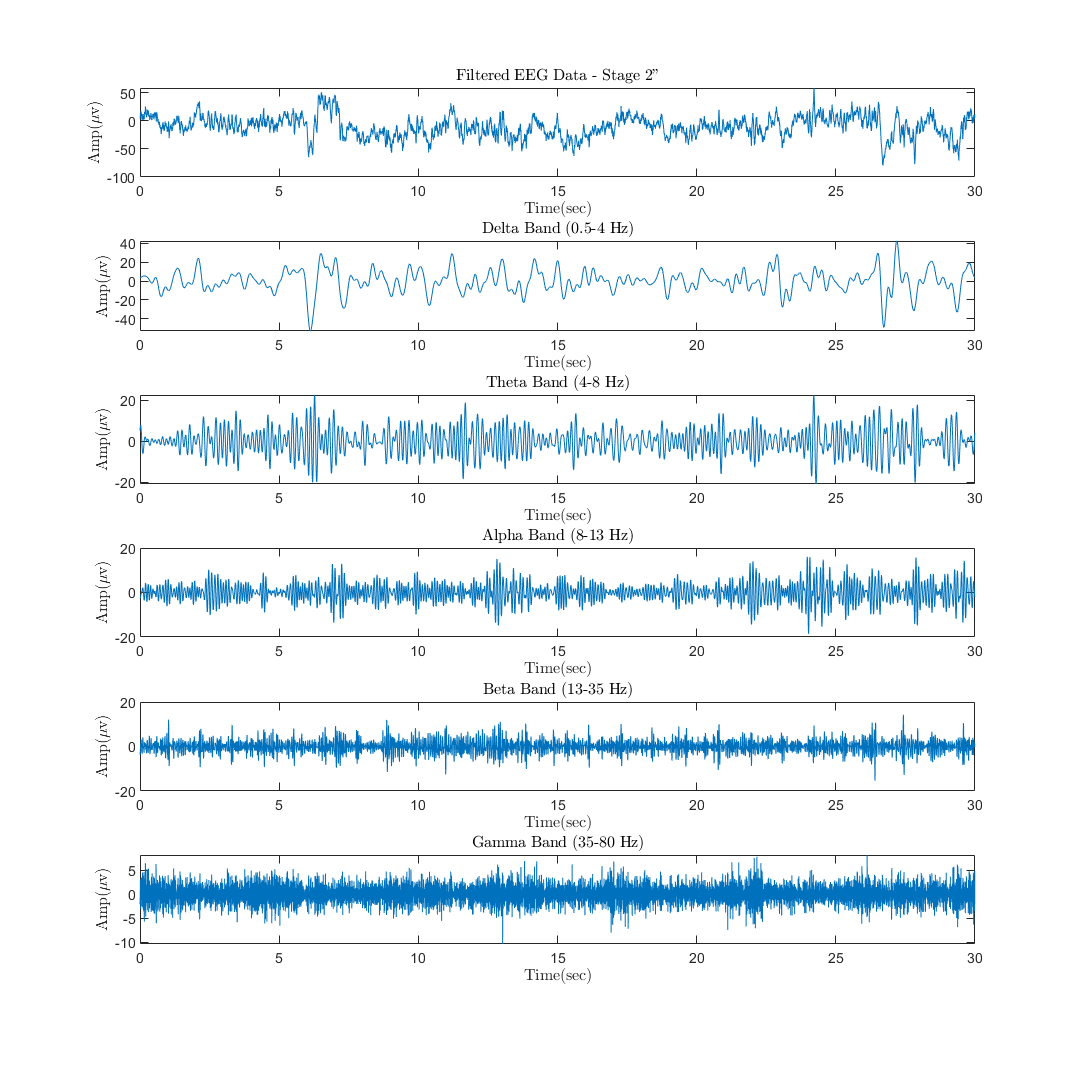

title('Beta Band (13-35 Hz)',"Interpreter","latex")
xlabel('Time(sec)',"Interpreter","latex")
ylabel('Amp($\mu$v)',"Interpreter","latex")
subplot(6,1,6)
plot(t(1:length(p1_s2)),p1_s2_gamma)
title('Gamma Band (35-80 Hz)',"Interpreter","latex")
xlabel('Time(sec)',"Interpreter","latex")
ylabel('Amp($\mu$v)',"Interpreter","latex")

# **Required Functions**

## 
$$\textrm{Fourier}\;\textrm{Transform}:$$


function X=FT(x)
X = (fftshift(fft(x))/length(x));
end

## 
$$\mathrm{Delta}\;\;\mathrm{Band}\;\left(0\ldotp 5-4\mathrm{Hz}\right):$$


function x_delta=delta(X,fs)
L = length(X);
f0 = L/2+1;
f1 = L/fs;
X_delta = zeros(1,L);
X_delta(f0-4*f1:f0+4*f1) = X(f0-4*f1:f0+4*f1);
x_delta = ifft(ifftshift(X_delta))*L;
end

## 
$$\mathrm{Theta}\;\mathrm{Band}\;\left(4-8\mathrm{Hz}\right):$$


function x_theta=theta(X,fs)
L = length(X);
f0 = L/2+1;
f1 = L/fs;
X_theta = zeros(1,L);
X_theta(f0+4*f1:f0+8*f1) = X(f0+4*f1:f0+8*f1);
X_theta(f0-8*f1:f0-4*f1) = X(f0-8*f1:f0-4*f1);
x_theta = ifft(ifftshift(X_theta))*L;
end

## 
$$\mathrm{Alpha}\;\mathrm{Band}\;\left(8-13\mathrm{Hz}\right):$$


function x_alpha=alpha(X,fs)
L = length(X);
f0 = L/2+1;
f1 = L/fs;
X_alpha = zeros(1,L);
X_alpha(f0+8*f1:f0+13*f1) = X(f0+8*f1:f0+13*f1);
X_alpha(f0-13*f1:f0-8*f1) = X(f0-13*f1:f0-8*f1);
x_alpha = ifft(ifftshift(X_alpha))*L;
end

## 
$$\mathrm{Beta}\;\mathrm{Band}\;\left(13-35\mathrm{Hz}\right):$$


function x_beta=beta(X,fs)
L = length(X);
f0 = L/2+1;
f1 = L/fs;
X_beta = zeros(1,L);
X_beta(f0+13*f1:f0+35*f1) = X(f0+13*f1:f0+35*f1);
X_beta(f0-35*f1:f0-13*f1) = X(f0-35*f1:f0-13*f1);
x_beta = ifft(ifftshift(X_beta))*L;
end

## 
$$\mathrm{Gamma}\;\mathrm{Band}\;\left(f>35\;\mathrm{Hz}\right):$$


function x_gamma=gamma(X,fs)
L = length(X);
f0 = L/2+1;
f1 = L/fs;
X_gamma = zeros(1,L);
X_gamma(f0+35*f1:L) = X(f0+35*f1:L);
X_gamma(1:f0-35*f1) = X(1:f0-35*f1);
x_gamma = ifft(ifftshift(X_gamma))*L;
end

## 
$$\textrm{Noise}\;\textrm{Reduction}:$$


function X_filtered=filter_noise(X,fs)
L = length(X);
f0 = L/2+1;
f1 = L/fs;
X_filtered = X;
X_filtered(f0-0.5*f1:f0+0.5*f1) = 0;
end